%Formulate the equations of motion for a rolling semicircle.  Actually
%generate the correct DEs.
clear all
syms x(t) y(t) Ff(t) N(t) theta(t) m r g

Izz = m*r^2*(1/4 - 16/9/pi^2) + m*r^2/4;
R_b_I = [cos(theta(t)) -sin(theta(t)) 0;sin(theta(t)) cos(theta(t)) 0;0 0 1];

rG=[x(t);y(t)];
F=[Ff(t);N(t)];

% Newton's 2nd
eq1=m*diff(rG,t,t)==F-m*g*[0;1];

% Euler's 2nd
r_CP_G = [0;-r;0] + R_b_I*[0;4*r/3/pi;0];
MG=cross(r_CP_G,[F;0]);
eq2=Izz*diff(theta(t),t,t)==MG(3);

% roll without slip
vG = cross([0;0;diff(theta(t),t)],-r_CP_G);
eq3 = diff(rG,t) == vG(1:2);

DES=[eq1;eq2];
disp_const=[];
vel_const=[eq3];


%Once again, because you've formulated it this way, it is expected that
%you'll need four state variables.  Because the dependence is so
%simple, you can actually get away with 2.  Watch out though!  If you do this, the solver
%will say that it can set x(t) and y(t) to be anything it likes, and choose
%0!  You'll get the correct governingODEs, but there is no way to calculate
%x(t) and y(t) out of theta, so your postprocessing equations will be
%incorrect. 
[governingODEs,PPs]=generateGoveringDEs(DES,[],vel_const,[theta,diff(theta)]);

The unknown functions are:
Ff(force)
N(force)
theta
x
y

Expected Number of State Variables:4


governingODEs

$$governingODEs = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-\frac{432345564227567616\,\pi \,\left(r\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+g\,\sin\left(\theta \left(t\right)\right)\right)}{r\,\left(576460752303423488\,{\cos\left(\theta \left(t\right)\right)}^{2}-864691128455135232\,\pi \,\cos\left(\theta \left(t\right)\right)+576460752303423488\,{\sin\left(\theta \left(t\right)\right)}^{2}+427981074009278211\,\pi^{2}\right)}$$


paramVals.m=1; paramVals.r=0.1; paramVals.g=9.81;
theta0=pi/6; omega0=0;

%Now you can timestep. You can solve for theta fine out of governing ODE.
%Just don't trust the results in the postprocessing equations for x and y. 
soln=timeStepODESystem(subs(governingODEs,paramVals),[0,20],[theta==theta0,diff(theta)==omega0],subs(PPs,paramVals),0);

The unknown functions (just the base functions, not derivatives) are: theta(t)


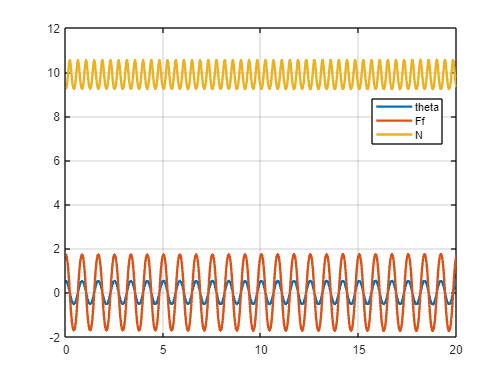

plot(soln.t,soln.theta,soln.t,soln.Ff,soln.t,soln.N,'LineWidth',2)
legend({"theta","Ff","N"},'Location','Best')
grid on

%You could have called x and y state variables, since they are in this
%formulation.  Now everything lines up, and the postprocessing equations
%can be trusted. 

[governingODEs,PPs]=generateGoveringDEs(DES,[],vel_const,[theta,diff(theta),x,y]);

The unknown functions are:
Ff(force)
N(force)
theta
x
y

Expected Number of State Variables:4


vpa(governingODEs,2)

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=-\frac{1.4e+18\,\left(r\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}+g\,\sin\left(\theta \left(t\right)\right)\right)}{r\,\sigma_{2}}\\ \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=-\frac{0.42\,\left(5.8e+17\,r\,\sigma_{4}\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}-1.4e+18\,r\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}+5.8e+17\,r\,{\sin\left(\theta \left(t\right)\right)}^{3}\,\sigma_{1}+1.0e+18\,r\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}+1.4e+18\,g\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-3.2e+18\,g\,\sin\left(\theta \left(t\right)\right)\right)}{\sigma_{2}}\\ \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)=-\frac{0.42\,\left(-5.8e+17\,r\,{\cos\left(\theta \left(t\right)\right)}^{3}\,\sigma_{1}+2.7e+18\,r\,\sigma_{4}\,\sigma_{1}-5.8e+17\,r\,\cos\left(\theta \left(t\right)\right)\,\sigma_{3}\,\sigma_{1}-4.2e+18\,r\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}+1.4e+18\,r\,\sigma_{3}\,\sigma_{1}+1.4e+18\,g\,\sigma_{3}\right)}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{2}=5.8e+17\,\sigma_{4}-2.7e+18\,\cos\left(\theta \left(t\right)\right)+5.8e+17\,\sigma_{3}+4.2e+18\\ \sigma_{3}={\sin\left(\theta \left(t\right)\right)}^{2}\\ \sigma_{4}={\cos\left(\theta \left(t\right)\right)}^{2} \end{array}$$

vpa(PPs,2)

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{\partial }{\partial t}x\left(t\right)=0.11\,r\,\left(4.0\,\cos\left(\theta \left(t\right)\right)-9.4\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \frac{\partial }{\partial t}y\left(t\right)=0.42\,r\,\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\theta \left(t\right)\\ \mathrm{Ff}\left(t\right)=-\frac{0.42\,m\,\left(5.8e+17\,r\,\sigma_{3}\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}-1.4e+18\,r\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}+5.8e+17\,r\,{\sin\left(\theta \left(t\right)\right)}^{3}\,\sigma_{1}+1.0e+18\,r\,\sin\left(\theta \left(t\right)\right)\,\sigma_{1}+1.4e+18\,g\,\cos\left(\theta \left(t\right)\right)\,\sin\left(\theta \left(t\right)\right)-3.2e+18\,g\,\sin\left(\theta \left(t\right)\right)\right)}{\sigma_{2}}\\ N\left(t\right)=\frac{0.11\,m\,\left(2.3e+18\,r\,{\cos\left(\theta \left(t\right)\right)}^{3}\,\sigma_{1}-1.1e+19\,r\,\sigma_{3}\,\sigma_{1}+2.3e+18\,r\,\cos\left(\theta \left(t\right)\right)\,\sigma_{4}\,\sigma_{1}+1.7e+19\,r\,\cos\left(\theta \left(t\right)\right)\,\sigma_{1}-5.4e+18\,r\,\sigma_{4}\,\sigma_{1}+5.4e+18\,g\,\sigma_{3}-2.6e+19\,g\,\cos\left(\theta \left(t\right)\right)+4.0e+19\,g\right)}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ \sigma_{2}=5.8e+17\,\sigma_{3}-2.7e+18\,\cos\left(\theta \left(t\right)\right)+5.8e+17\,\sigma_{4}+4.2e+18\\ \sigma_{3}={\cos\left(\theta \left(t\right)\right)}^{2}\\ \sigma_{4}={\sin\left(\theta \left(t\right)\right)}^{2} \end{array}$$

%Now you can timestep.  You'll need to give initial conditions for x,y,
%because they are state variables. 

soln=timeStepODESystem(subs(governingODEs,paramVals),[0,20],[theta==theta0,diff(theta)==omega0,x==0,y==1],subs(PPs,paramVals),0);

The unknown functions (just the base functions, not derivatives) are: theta(t),x(t),y(t)


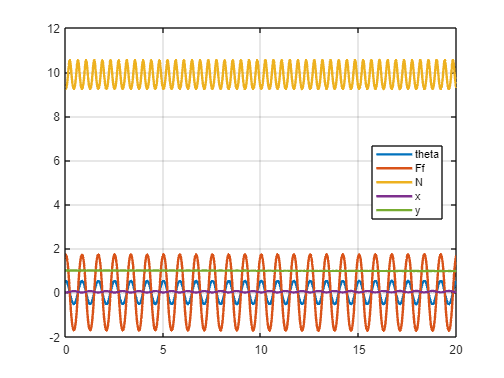

plot(soln.t,soln.theta,soln.t,soln.Ff,soln.t,soln.N,soln.t,soln.x,soln.t,soln.y,'LineWidth',2)
legend({"theta","Ff","N","x","y"},'Location','Best')
grid on